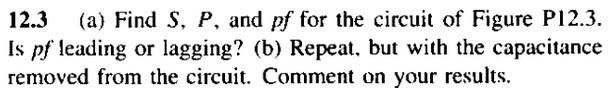

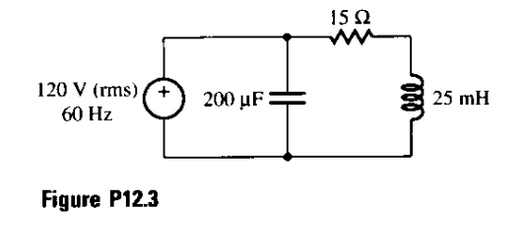

clc, clear, close all
format short g

vf = 120; %[V]
f = 60; %[Hz]
w = 2*pi*f;
c = 200e-6; %[F]
l = 25e-3; %[H]
r = 15; %[ohms]
gr = 180/pi; %factor de conversion de rads a grados

zc = 1/(j*w*c);
zl = j*w*l;

zeq = 1/((1/(zc))+(1/(zl+r)));
z_eq = [abs(zeq) angle(zeq)*gr] %carga capacitiva

z_eq =        15.175      -43.505


Con la impedancia equivalente podemos calcular la correinte rms entregada por la fuente:

i_f = vf/zeq;
i_fasor = [abs(i_f) angle(i_f)*gr] %[A]

i_fasor =        7.9079       43.505


con tensiones y corrientes hallamos la potencia aparente, el factor de potencia y la potencia activa:

S = abs(vf)*abs(i_f) %[VA]

S =        948.95


fp = cos(angle(i_f)) %en adelanto

fp =       0.72531


P = S*fp %potencia activa consumida

P =        688.28


lo verificamos en el simulador:

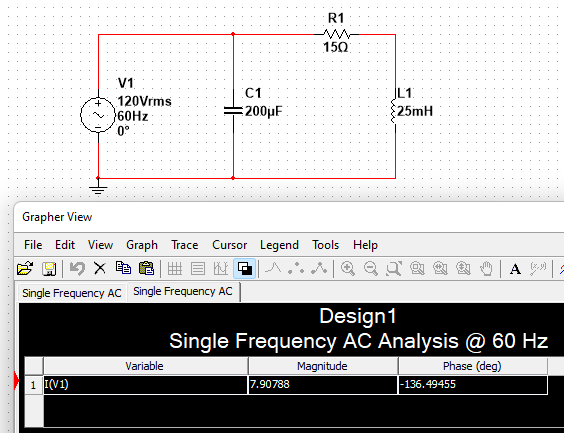

**b)** repetimos el ejercicio pero sin el capacitor

zeq = zl + r;
z_eq = [abs(zeq) angle(zeq)*gr] %angulo positivo = carga inductiva

z_eq =        17.715       32.142


i_f = vf/zeq;
i_fasor = [abs(i_f) angle(i_f)*gr] %[A]

i_fasor =        6.7739      -32.142



S = abs(vf)*abs(i_f) %[VA]

S =        812.86


fp = cos(angle(i_f)) %en atraso

fp =       0.84673


P = S*fp %potencia activa consumida

P =        688.28


En este caso vemos que el factor de potencia aumenta sin el capacitor, lo verificamos en el simulador: